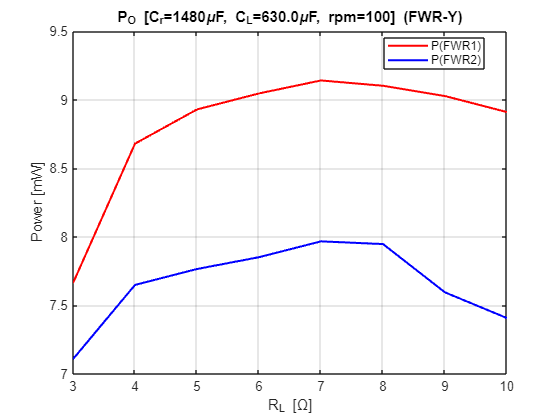


% Dati misurati (Y1_100rpm.csv, Y2_100rpm.csv - tabella "C = 630 uF"):
% sweep della resistenza di carico R_L, C_m e rpm fissi, per i due bridge FWR-Star.
% Y2_100rpm.csv riporta questa tabella due volte: la prima etichettata per errore
% "C = 730 uF" (nota dell'utente nel CSV: "devo mettere 630") con due valori di Pi
% leggermente diversi a R=10 e R=11; qui si usano i valori della seconda tabella,
% quella corretta ed etichettata C = 630 uF. Nessun'altra anomalia di virgola trovata.

C_r = 1480e-6;     % F - condensatore di filtro/raddrizzatore, fisso
C_L = 630e-6;      % F - condensatore di compensazione C_m, fisso durante lo sweep
rpm_b1 = 100;      % rpm fisso durante lo sweep

R_L = [9 10 11 12 13 14 15 16 17 18 19];   % Ohm (asse x)

Po_b1_mW = [19.1471 19.9766 20.2145 20.5559 20.8845 21.1113 21.1838 21.2436 20.9339 20.7692 20.2796];
Pi_b1_mW = [57.4484 55.9309 54.9884 54.8756 53.9007 53.0564 52.0283 50.3798 49.4933 48.4282 47.1675];

Po_b2_mW = [18.8588 20.5706 20.9188 21.0415 21.3806 21.4806 21.5729 21.7837 21.7189 21.6928 21.6131];
Pi_b2_mW = [58.7404 59.0645 58.0117 56.8851 55.8145 54.3774 53.6413 52.6900 51.4718 50.8316 49.8990];

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;


figure;
plot(R_L, P_real_b1*1000, 'r-', 'LineWidth', 1.5);hold on;
plot(R_L, P_real_b2*1000, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR-Y)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
legend(["P(FWR1)","P(FWR2)"], "Location","best");
hold off;

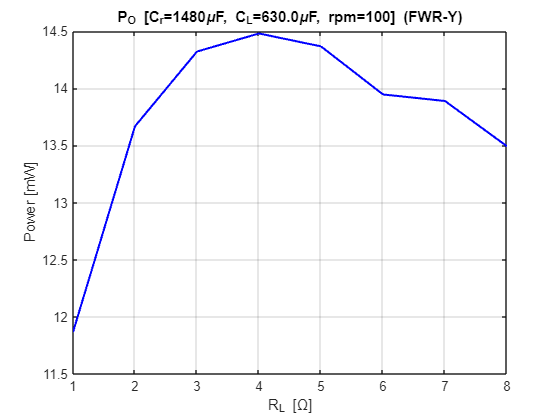


% figure;
% plot(R_L, (P_real_b1+P_real_b2)*1000, 'b-', 'LineWidth', 1.5)
% grid on;
% title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (Y)', C_r*1e6,C_L*1e6,rpm_b1));
% xlabel('R_L [\Omega]');
% ylabel('Power [mW]');
% xlim([min(R_L), max(R_L)]);
% hold off;


% Dati misurati con i due bridge FWR-Star gia' collegati in parallelo
% (Y_1+2_100rpm.csv), C_m = 630 uF fisso, rpm = 100: mostrati in una figura separata
% perche' il range di R_L di questa misura (3-9 Ohm) e' diverso da quello dei bridge
% singoli sopra (9-19 Ohm). Il CSV non riporta Pi per questa misura (solo Po).

R_L_tot = [3 4 5 6 7 8 9];   % Ohm (asse x, misura con i due bridge in parallelo)

Po_tot_mW = [45.0254 46.2523 47.3998 48.2790 48.3566 48.3402 47.3302];

P_real_tot_meas = Po_tot_mW/1000;

figure;
plot(R_L_tot, P_real_tot_meas*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR-Y)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L_tot), max(R_L_tot)]);
hold off;